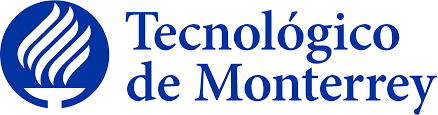

## Implementación de robótica inteligente (TE3002B)

## Evaluación 11.2 (Planeación de Trayectorias)

### Pamela Hernández Montero A01736368

**1. Obtener** el mapa de puntos para generar la planeación de trayectorias a partir de tu rostro, marcando **set-****points** con el software Geogebra. 

**2. Planear** la trayectoria que debe seguir el algoritmo empleando el mapa de puntos obtenido, considerando la descripción más próxima a los rasgos físicos de tu rostro (Forma de la cara, forma del cabello, ojos, cejas, nariz, boca y orejas), (barba en caso de que aplique).

Para estos pasos fue necesario realizar el trazado de la trayectoria considerando el movimiento del robot, por lo que algunos puntos se trazaron sobre la misma figura pero en sentido contrario, regresando a puntos ya trazados para dibujar más detalles. Los puntos remarcados fueron los siguientes:

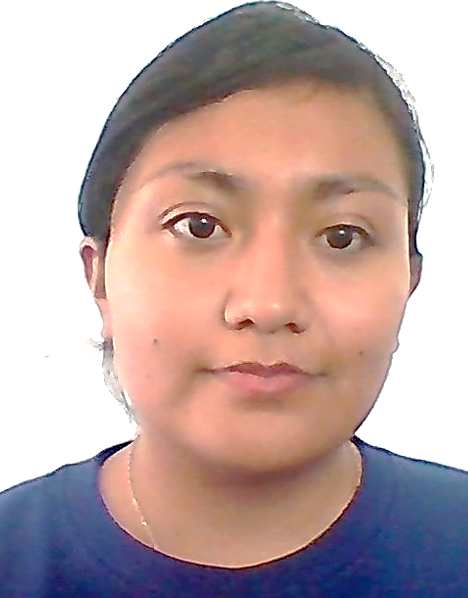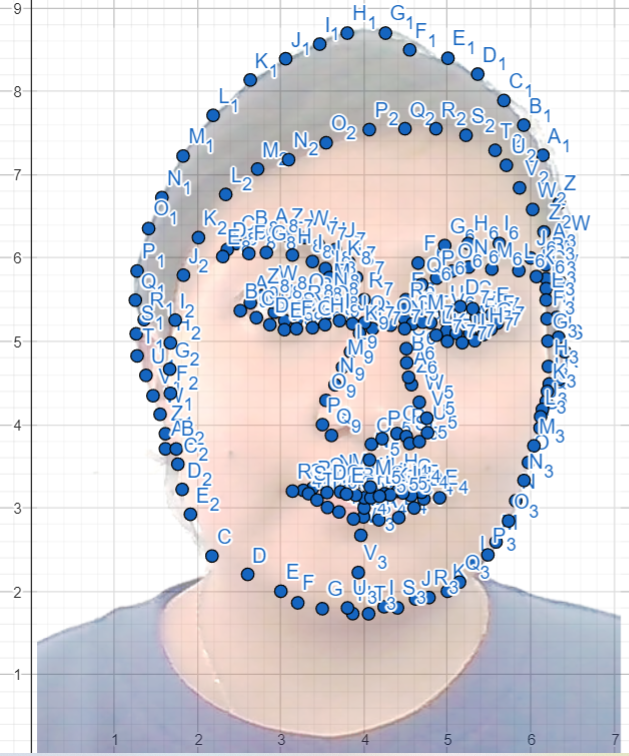

Para la extracción de puntos, copié y pegué en el orden del recorrido los puntos de Geogebra. Al principio decidí hacerlo de forma manual, pero conforme avanzaba en el trazado, decidí tomar capturas de los puntos y enviarlas a una IA que extrae texto de las imágenes, facilitando la extracción de datos. Sin embargo, de vez en cuando tenía que verificar los signos debido a que podía haber signos negativos.

**3. Implementar** el código requerido para generar la planeación de trayectorias empleado la técnica que consideres más eficiente para esta aplicación (**Control en lazo abierto, control de posición, control de trayectorias** **ó** **PurePursuit** **(****way-points****)**). Considerando el ajuste de los parámetros cinemáticos del robot móvil como: Velocidad angular (w), velocidad lineal (v), ancho de la muestra (ts), tiempo de simulación (t), ganacias, etc.

Debido a la simplicidad de usar waypoints, decidí utilizar el código "Differential drive vehicle following waypoints using the Pure Pursuit algorithm" empleado durante el curso, donde consideré dejar los mismos valores de la Evaluación 11 debido a que tienen una configuración buena ante las curvas y con poco ruido.

La ventaja de usar waypoints es que permite definir puntos clave en la trayectoria que el robot debe seguir, simplificando la planificación del movimiento. Con waypoints, se pueden especificar posiciones exactas por las que el robot debe pasar, lo que facilita el control de su ruta y asegura que se mantenga en el camino deseado.

En este caso el uso de PurePursuit (way-points) en comparación con otros algoritmos como el control en lazo abierto, control de posición y control de trayectorias ofrece una solución más eficiente y adecuada para aplicaciones que requieren precisión en el seguimiento de trayectorias predefinidas. PurePursuit permite una implementación y ajuste más simples, proporciona retroalimentación constante y corrección en tiempo real, y facilita el seguimiento preciso de trayectorias curvilíneas mediante los waypoints. Además, este método es menos intensivo computacionalmente y más flexible, permitiendo ajustes rápidos y mejor manejo de trayectorias detalladas, como en este caso.

%% Define Vehicle
R = 0.02;                % Wheel radius [m]
L = 0.5;                % Wheelbase [m]
dd = DifferentialDrive(R,L);

%% Simulation parameters
sampleTime = 0.1;               % Sample time [s]
tVec = 0:sampleTime:128;       % Time array
initPose = [1.9142748432291;2.9238290950142; pi/2];        % Initial pose (x y theta)
pose = zeros(3,numel(tVec));    % Pose matrix
pose(:,1) = initPose;

% Define waypoints
waypoints = [1.9142748432291,2.9238290950142;2.1727765080204566, 2.422472023631157; 2.6017815976096634, 2.202626528712856; 3.0, 2.0;
3.2029112592066937, 1.8608077015302313; 3.497582661950336, 1.7900865648717572; 3.862975201352452, 1.731152284323029; 4.240154596864314, 1.8136602770912487; 4.617333992376176, 1.9079551259692142;
5.0, 2.0; 5.336332215070663, 2.3322819459200588; 5.583856193375323, 2.591592780334464; 5.819593315570236, 3.086640736943783; 5.972822444996931, 3.5463281252238645;
6.112115269268445, 3.9602676919884874; 6.186255506535554, 4.281542053479293; 6.342773785210562, 4.545151785984569; 6.408676218336881, 4.8746639516161645; 6.334535981069772, 5.047657838572752;
6.309822568647402, 5.286554158655659; 6.351706897264922, 5.714209116889901; 6.4338492461377035, 6.182420505464752; 6.343492662377644, 6.658846128926882; 6.14635102508297, 7.233842571036349;
5.916352448239183, 7.595268906076585; 5.678139636508118, 7.890981362018597; 5.363882876707562, 8.208046243978291; 5.005885889218406, 8.398232143581907; 4.547202248997924, 8.498918796313232;
4.256329696662984, 8.700292101775883; 3.797646056442502, 8.700292101775883; 3.466532725910009, 8.568245619640889; 3.057551878544706, 8.39274951592996; 2.6328141921269945, 8.137906904079333;
2.1868396213883976, 7.713169217661621; 1.825812587933343, 7.224720878281253; 1.570969976082716, 6.725654096740441; 1.4116933436760744, 6.354008621124943; 1.273653595590318, 5.844323397423689;
1.2524167112694327, 5.493914806129077; 1.3586011328738605, 5.260309078599335; 1.2630351534298754, 5.09041400403225; 1.273653595590318, 4.8249529500211805; 1.379838017194746, 4.5913472224914385;
1.4647855544782884, 4.347123052801255; 1.5497330917618306, 4.124135767431956; 1.6134437447244874, 3.8905300399022145; 1.6134437447244874, 3.7100165231746867; 1.7440349698434596, 3.708216734708014;
1.7632664640994613, 3.5255175392759983; 1.8147227553593732, 3.2224853586232047; 1.9142748432290568, 2.9238290950141543; 1.6736906308773216, 4.375630376447038; 1.665394623554848, 4.665990632733615;
1.6736906308773216, 4.981238910987613; 1.731762682134637, 5.255007152629242; 1.8302368190271776, 5.7941776221530175; 2.0105930781673136, 6.245068270003358; 2.3374887978588097, 6.763592515031251;
2.7207458485315983, 7.067943702330231; 3.092730633008129, 7.180666364292816; 3.5436212808584684, 7.383567155825469; 4.0621455258863595, 7.541378882573089; 4.490491641344182, 7.552651148769347;
4.862476425820712, 7.552651148769347; 5.2231889441009836, 7.4737452853955375; 5.572629196184996, 7.293389026255402; 5.707896390540099, 7.113032767115265; 5.865708117287717, 6.84249837840506;
6.023519844035336, 6.583236255891114; 6.158787038390438, 6.31270186718091; 6.203876103175472, 6.087256543255739; 6.181331570782955, 5.918172550311861; 6.1860168892388545, 5.753112330908658;
6.1860168892388545, 5.632461463358809; 6.1860168892388545, 5.496073526128547; 6.196508269025798, 5.270508860709266; 6.206999648812741, 5.002978676142211; 6.212245338706213, 4.698728662320856;
6.222736718493156, 4.488901066581989; 6.14033872864568, 4.183229589015555; 6.2, 4.4; 6.118232968288255, 4.09480654758592; 6.038652231001583, 3.7455355339388583;
5.919281125071576, 3.3299472392195697; 5.733592738069341, 2.8436205113565727; 5.4860082220663635, 2.436874520780248; 5.145579512562267, 2.109709267490595; 4.77862389062928, 1.9240208804883598;
4.4, 1.8; 4.053554950906269, 1.729490189343161; 3.8, 1.8; 3.92976269290478, 2.224659221349121; 3.9607107574051525, 2.671195580568782;
3.9916588219055247, 2.8922531841428714; 4.177347208907759, 2.8568839675710174; 4.416089420767775, 2.883410879999908; 4.6, 3.0; 4.716727761628535, 3.1088896356454794;
4.906837300702251, 3.1221530918599245; 4.690200849199645, 3.1884703729321515; 4.561987439126673, 3.2592088060758604; 4.416089420767775, 3.329947239219569; 4.252506794122949, 3.3343683912910507;
4.124293384049978, 3.2989991747191962; 4.00492227811997, 3.2724722622903055; 3.917038158217388, 3.336181915572584; 3.7875481377537574, 3.3272515693337126; 3.6357322516929487, 3.304925703736535;
3.5196377505876244, 3.2781346650199215; 3.3812173838851223, 3.2379481069450016; 3.269588055899234, 3.2111570682283883; 3.140098035435603, 3.202226721989517; 3.332100479571331, 3.1709705101534684;
3.434799461318349, 3.095062567123064; 3.5598243086625443, 3.0057591047343526; 3.6982446753650464, 2.952177027301126; 3.8723864270230326, 2.8673387380318505; 4.0, 3.0;
4.001876447486664, 3.1218536058396773; 3.899177465739646, 3.153109817675726; 3.7161053678427884, 3.1932963757506463; 3.555359135543109, 3.184366029511775; 3.7875481377537574, 3.1665053370340335;
4.082249563636504, 3.1218536058396777; 4.247460969055618, 3.170970510153469; 4.4, 3.2; 4.564488260535542, 3.148644644556291; 4.46625445190796, 3.17990085639234;
4.314438565847152, 3.1575749907951622; 4.184948545383521, 3.13971429831742; 4.073319217397632, 3.251343626303309; 4.064388871158761, 3.5773012640221045; 4.086714736755939, 3.7648385350383977;
4.21620475721957, 3.8318161318299313; 4.394811681996992, 3.894328555502029; 4.50644100998288, 3.8586071705465446; 4.5466275680578, 3.773768881277269; 4.662722069163125, 3.796094746874447;
4.760955877790707, 3.9032589017409; 4.752025531551835, 4.077400653398887; 4.662722069163125, 4.2694030975346156; 4.568953433654978, 4.479266234148087; 4.533232048699493, 4.568569696536798;
4.510906183102316, 4.742711448194784; 4.50644100998288, 4.9123880267333355; 4.486268489957753, 5.271782701770868; 4.5, 5.5; 4.64869069234605, 5.9395184227005355;
4.967519459997152, 6.150065722092773; 5.250254404895298, 6.174128270594744; 5.623223906675832, 6.174128270594744; 6.0, 6.0; 6.068381053962275, 5.777096220312238;
5.857833754570038, 5.8492838658181485; 5.532989349793445, 5.867330777194626; 5.25627004202079, 5.891393325696596; 5.057754016879539, 5.843268228692656; 4.871269265989271, 5.759049308935761;
4.690800152224497, 5.6808460263043585; 4.492284127083246, 5.386079807155226; 4.582518683965633, 5.211626330515943; 4.799081620483362, 5.223657604766928; 4.973535097122644, 5.3439703472767786;
4.985566371373629, 5.241704516143406; 4.991582008499122, 5.127407410759048; 5.1058791138834785, 5.097329225131586; 5.268301316271775, 5.097329225131586; 5.346504598903177, 5.283813976021853;
5.30439513902473, 5.392095444280718; 5.154004210887418, 5.416157992782688; 5.526973712667952, 5.319907798774809; 5.599161358173862, 5.217641967641436; 5.52095807554246, 5.145454322135526;
5.430723518660072, 5.079282313755108; 5.3284576875267, 5.007094668249199; 5.178066759389388, 4.983032119747229; 5.0, 5.0; 4.865253628863779, 5.073266676629616;
4.702831426475482, 5.229673241892421; 4.486268489957753, 5.151469959261019; 4.317830650443963, 5.193579419139466; 4.101267713926235, 5.151469959261019; 4.005017519918355, 5.223657604766928;
4.0, 5.5; 3.908767325910475, 5.765064946061253; 3.818532769028088, 5.945534059826028; 3.656110566639791, 6.101940625088833; 3.4515789043730467, 6.162096996343758;
3.2831410648592576, 6.246315916100653; 3.0545468540905434, 6.270378464602623; 2.8620464660747844, 6.270378464602623; 2.6274366181805777, 6.240300278975161; 2.4650144157922806, 6.174128270594744;
2.3567329475334162, 6.101940625088833; 2.302592213403984, 6.0177217053319385; 2.615405343929593, 6.053815528084893; 2.8259526433218296, 6.065846802335878; 3.138765773847438, 6.035768616708416;
3.379391258867137, 5.957565334077013; 3.5357978241299417, 5.873346414320118; 3.7403294863966856, 5.873346414320118; 3.5839229211338814, 5.765064946061253; 3.565876009757404, 5.608658380798448;
3.565876009757404, 5.500376912539584; 3.565876009757404, 5.337954710151286; 3.391422533118122, 5.440220541284658; 3.2711097906082727, 5.482330001163106; 3.2590785163572873, 5.3439703472767786;
3.19290650797687, 5.259751427519883; 3.048531216965051, 5.247720153268898; 2.922202837329709, 5.349985984402271; 2.9161872002042166, 5.47029872691212; 2.9161872002042166, 5.578580195170986;
2.7778275463178894, 5.548502009543523; 2.63345225530607, 5.464283089786628; 2.5131395127962204, 5.368032895778748; 2.70563990081198, 5.283813976021853; 2.868062103200277, 5.199595056264958;
3.0425155798395584, 5.139438685010033; 3.1868908708513777, 5.151469959261019; 3.379391258867137, 5.163501233512004; 3.5297821870044492, 5.199595056264958; 3.704235663643731, 5.247720153268898;
3.8606422289065354, 5.211626330515943; 3.94486114866343, 5.097329225131586; 3.8365796804045655, 4.874750651488363; 3.7403294863966856, 4.688265900598096; 3.6500949295142986, 4.477718601205859;
3.541813461255434, 4.291233850315591; 3.5, 4.0; 3.6079854696358513, 3.870139251531116;4.0867147367559, 3.7648385350384]

waypoints =     1.9143    2.9238
    2.1728    2.4225
    2.6018    2.2026
    3.0000    2.0000
    3.2029    1.8608
    3.4976    1.7901
    3.8630    1.7312
    4.2402    1.8137
    4.6173    1.9080
    5.0000    2.0000


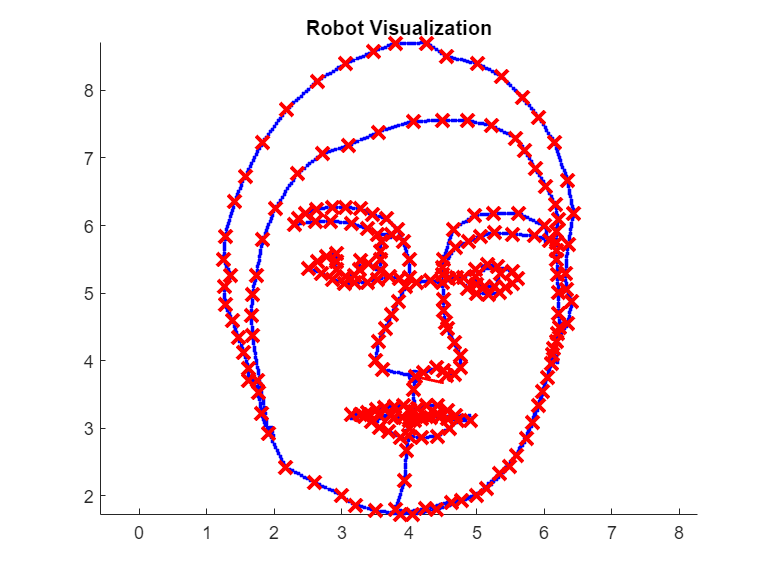


% Create visualizer
viz = Visualizer2D;
viz.hasWaypoints = true;

%% Pure Pursuit Controller
controller = controllerPurePursuit;
controller.Waypoints = waypoints;
controller.LookaheadDistance = 0.1;
controller.DesiredLinearVelocity = 0.5;
controller.MaxAngularVelocity = 500;

%% Simulation loop
close all
r = rateControl(1/sampleTime);
for idx = 2:numel(tVec) 
    % Run the Pure Pursuit controller and convert output to wheel speeds
    [vRef,wRef] = controller(pose(:,idx-1));
    [wL,wR] = inverseKinematics(dd,vRef,wRef);
    % Compute the velocities
    [v,w] = forwardKinematics(dd,wL,wR);
    velB = [v;0;w]; % Body velocities [vx;vy;w]
    vel = bodyToWorld(velB,pose(:,idx-1));  % Convert from body to world
    % Perform forward discrete integration step
    pose(:,idx) = pose(:,idx-1) + vel*sampleTime; 
    % Update visualization
    viz(pose(:,idx),waypoints);
    waitfor(r);
end